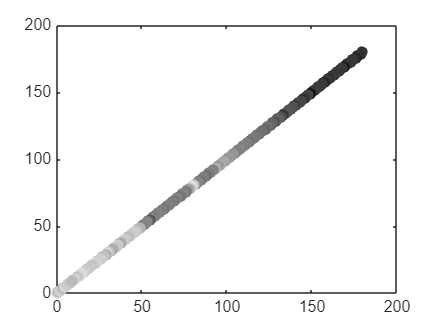

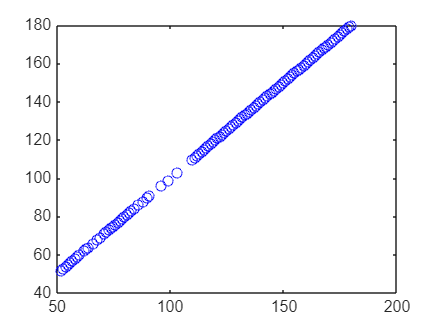

% Convert voltage to distance (replace with your actual calibration equation)
distance = -0.152 .* volts + 84.8;  % Example calibration function

% Convert to spherical coordinates (motor angles in degrees)
motor1 = -1 .* position1 + 180;  % Angle for motor 1
motor2 = -1 .* position2 + 180;  % Angle for motor 2

% Convert spherical coordinates to Cartesian coordinates
[x, y, z] = sph2cart(deg2rad(motor1), deg2rad(motor2), distance);

% Normalize x and sensor data for visualization
x = rescale(x);
n = rescale(volts);

% Plot data based on intensity (n corresponds to the sensor data)
figure;
for i = 1:length(position1)
    plot(motor1(i), motor2(i), "color", [1-n(i) 1-n(i) 1-n(i)], "Marker", ".", "MarkerSize", 20);
    hold on;
end
hold off;

% Highlight any points where sensor data indicates an object is detected
figure;
for i = 1:length(volts)
    if volts(i) > 2  % Threshold for detected object (adjust as needed)
        plot(motor1(i), motor2(i), '-o', 'Color', "b");
        hold on;
    end
end
hold off;